## TALLER 6

Organizamos la información

clear
clc
% Información suministrada

%Reacciones Fase Gaseosa
% A -> X ,  rX
% A -> B ,  rB
% A -> Y ,  rY

% Condiciones de operación
T0 = 27 + 273.15; %K
P0 = 4 ; %atm
Q0 = 10 ; %L/min

%Cinética
k1_T0 = 0.004 ; % (mol/L)^0.5/min
k2_T0 = 0.3 ; % min^-1
k3_T0 = 0.25 ; % L/mol/min
E1 = 20000 ; %cal/mol
E2 = 10000 ; %cal/mol
E3 = 30000 ; %cal/mol


Una vez organizada la información procedemos a hacer los cálculos preliminares

R = 0.08205746 ; %Constante de los gases atmL/molK
Rk = 1.987207 ; %Constante de los gases cal/molK

% Flujo de entrada A

%Asumiendo gas ideal
% Fi/Q = Ci = Pi/RT
CA0 = P0/R/T0

CA0 = 0.1624

FA0 = Q0*CA0

FA0 = 1.6241


% Cinética

k1 = @(T) k1_T0*exp(-E1/Rk*(1./T-1/T0)) ; % (mol/L)^0.5/min
k2 = @(T) k2_T0*exp(-E2/Rk*(1./T-1/T0)) ; % min^-1
k3 = @(T) k3_T0*exp(-E3/Rk*(1./T-1/T0)) ; % L/mol/min

rX = @(T,CA) k1(T).*CA.^0.5 ;% (mol/L)^0.5/min
rB = @(T,CA) k2(T).*CA ; % min^-1
rY = @(T,CA) k3(T).*CA.^2 ; %L/mol/min


### Dibujar $S_{B/X}$, $S_{B/Y}$ y $S_{B/XY}$ en función de A

Empezamos por definir las expresiones de la selectividad instantánea


$$S_{B/X} = \frac{r_{B}}{r_{X}}$$



$$S_{B/X} = \frac{r_{B}}{r_{Y}}$$



$$S_{B/X} = \frac{r_{B}}{r_{X}+r_{Y}}$$


Con base en esto procedemos a graficar

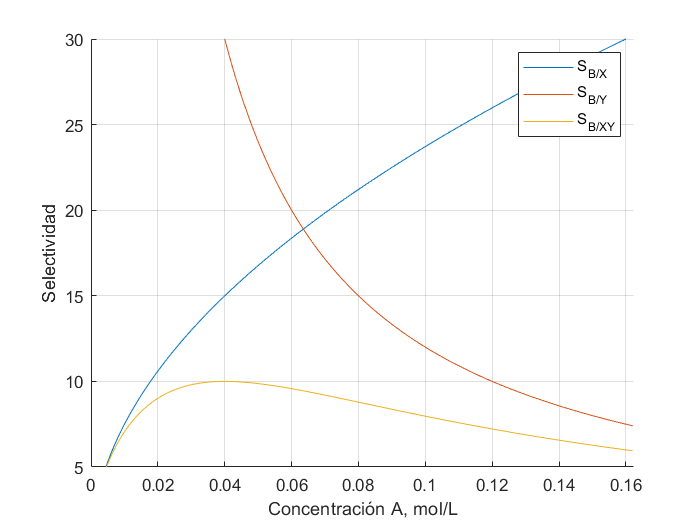

% Creamos las funciones de selectividad
S_BX = @(T0,CA) rB(T0,CA)./rX(T0,CA) ;
S_BY = @(T0,CA) rB(T0,CA)./rY(T0,CA) ;
S_BXY = @(T0,CA) rB(T0,CA)./(rY(T0,CA)+rX(T0,CA)) ;

CAgraf = 0:.001:CA0 ;

figure('color','white')
hold on
plot(CAgraf,S_BX(T0,CAgraf))
plot(CAgraf,S_BY(T0,CAgraf))
plot(CAgraf,S_BXY(T0,CAgraf))
xlabel('Concentración A, mol/L')
ylabel('Selectividad')
axis([0 CA0 5 30])
grid on
legend('S_{B/X}','S_{B/Y}','S_{B/XY}')

Vemos que en la gráfica de selectividad instantánea tenemos un valor máximo con un valor de $Smax$ a una concentración $CA_{Smax}$

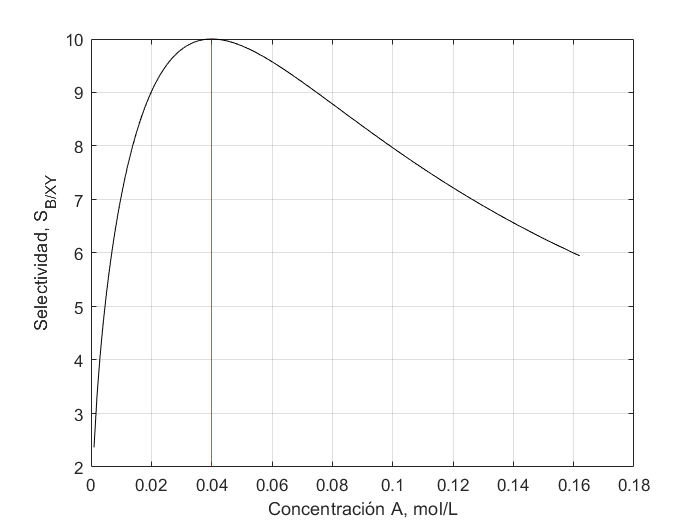

[Smax,indmax] = max(S_BXY(T0,CAgraf)) ;
CA_Smax = CAgraf(indmax)  ;
figure('color','white')
plot(CAgraf,S_BXY(T0,CAgraf),'k')
xlabel('Concentración A, mol/L')
ylabel('Selectividad, S_{B/XY}')
xline(CAgraf(indmax),'r')
grid on

Smax

Smax = 10

CA_Smax

CA_Smax = 0.0400

Con base en que la selectividad instantánea es igual a la global para un reactor CSTR y, en cambio, para un PFR la selectividad global depende del área bajo la curva; sería recomendable emplear para el arreglo inicialmente un reactor CSTR (para tener el valor de selectividad máxima a la salida) y, después, el reactor PFR. Sin embargo, se compararán los diferentes arreglos que se pueden tener: CSTR+PFR, PFR+CSTR, CSTR y PFR, para ver los resultados que tendría cada uno.

### A. Arreglo CSTR + PFR

El balance de materia para el CSTR es, en este caso


$$F_{A,0} -  F_{A,1}  + R_A V_1= 0$$


Donde $R_A$ es la rapidez de reacción global, es decir, 


$$R_A = \sum_j{r_{A,j}} = -(r_{X} + r_{B} + r_{Y})$$


El balance de materia se puede reescribir y despejar el volumen del CSTR


$$Q_0C_{A,0} - Q_1C_{A,1}  + R_{A(C_{A,1})} V_1= 0$$



$$\rightarrow V_1= \frac{Q_1C_{A,1}-Q_0C_{A,0}}{R_{A,C_{A,1}}}$$


Note que el reactor trabaja isotérmicamente, no se tienen en cuentra caídas de presión y todas las reacciones consumen y crean la misma cantidad de moles (los moles permanecen constantes), entonces


$$Q_1=Q_0$$


Encontrando


$$V_1= \frac{Q_0\left(C_{A,1}-C_{A,0}\right)}{R_{A,(C_{A,1})}}$$


CA1 = CA_Smax   ;
V1CSTR = Q0*(CA1-CA0)/(-rX(T0,CA1)-rB(T0,CA1)-rY(T0,CA1)) 

V1CSTR = 92.7322

De manera análoga al balance de materia elaborado para A, también se puede hacer para las otras especies


$$C_{X,1}  = r_{X(C_{A,1})} \frac{V_1}{Q_0}$$



$$C_{B,1}  = r_{B(C_{A,1})} \frac{V_1}{Q_0}$$



$$C_{Y,1}  = r_{Y(C_{A,1})} \frac{V_1}{Q_0}$$


CX1 = rX(T0,CA1)*V1CSTR/Q0

CX1 = 0.0074

CB1 = rB(T0,CA1)*V1CSTR/Q0

CB1 = 0.1113

CY1 = rY(T0,CA1)*V1CSTR/Q0

CY1 = 0.0037

y, por tanto, se calcula una conversión de

xA1 = (CA0-CA1)/CA0

xA1 = 0.7537

Para el caso del PFR tendremos que


$$\frac{dF_A}{dV} = R_A$$



$$\rightarrow V2PFR =Q_0 \int_{C_{A1}}^{C_{A2}} \frac{dC_A}{R_{A,(C_A)}$$


Donde


$$C_{A2} = C_{A0}(1-x_{A2})$$


Como $x_{A2}=0.99$ entonces

xA2 = 0.99 ;
CA2 = CA0*(1-0.99) 

CA2 = 0.0016

Encontrando

V2PFR = Q0*integral(@(CA) -1./(rX(T0,CA)+rB(T0,CA)+rY(T0,CA)),CA1,CA2)

V2PFR = 91.1917

Ahora, realizando el balance de materia para todas las especies se encuentra el siguiente sistema de ecuaciones


$$\frac{dC_A}{dV} =  R_A = \frac{-r_{X,(C_A)}-r_{Y,(C_A)}-r_{B,(C_A)}}{Q_0}$$



$$\frac{dC_B}{dV} = \frac{r_{,(C_A)}}{Q_0}$$



$$\frac{dC_X}{dV} = \frac{r_{B,(C_A)}}{Q_0}$$



$$\frac{dC_Y}{dV} = \frac{r_{Y,(C_A)}}{Q_0}$$


Donde en $V=0$ se tendrán las concentraciones de salida del reactor anterior $C_{i,1}$. Se resuelve el sistema de ecuaciones hasta $V_{2,PFR}$ (encontrado anteriormente), obteniendo los siguientes perfiles de concentraciones

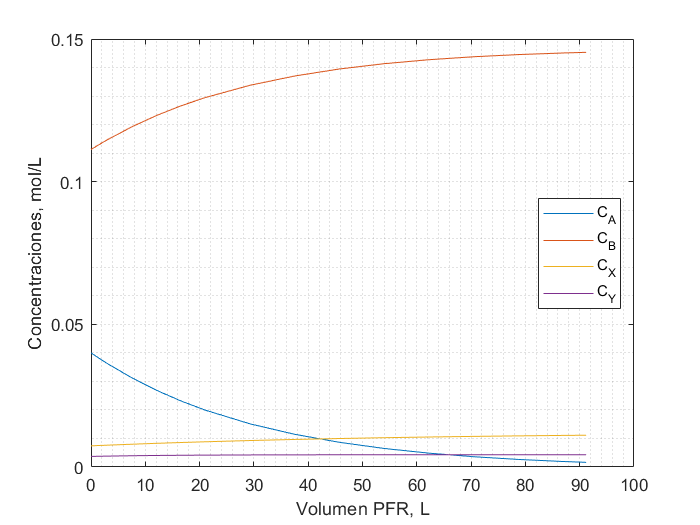

% Ci = [A,B,X,Y]

%Condiciones iniciales
Ci0 = [CA1,CB1,CX1,CY1] ;

%Sistema Ecuaciones
dCidV = @(Ci) [-(rX(T0,Ci(1))+rB(T0,Ci(1))+rY(T0,Ci(1)))/Q0;...
                rB(T0,Ci(1))/Q0 ;...
                rX(T0,Ci(1))/Q0 ;...
                rY(T0,Ci(1))/Q0 ] ;

%Intervalo de solución
vspan = [0,V2PFR] ;
[v,Ci] = ode15s(@(v,Ci) dCidV(Ci'),vspan,Ci0') ;
figure('color','white')
plot(v,Ci)
xlabel('Volumen PFR, L')
ylabel('Concentraciones, mol/L')
legend('C_A','C_B','C_X','C_Y','location','best')
grid minor

Y las concentraciones a la salida

CB2 = Ci(end,2) %mol/L

CB2 = 0.1453

CX2 = Ci(end,3) %mol/L

CX2 = 0.0111

CY2 = Ci(end,4) %mol/L

CY2 = 0.0043

Encontrando como selectividad global


$$\hat{S}_{B/XY} = \frac{F_{B2}}{F_{X2}+F_{Y2}} = \frac{C_{B2}}{C_{X2}+C_{Y2}}$$


SBXY = CB2/(CX2+CY2)

SBXY = 9.4084

y como rendimiento global de la reacción


$$\hat{Y}_{B} = \frac{F_{B2}}{F_{A0}-F_{A2}} = \frac{C_{B2}}{C_{A0}-C_{A2}}$$


YBXY = CB2/(CA0-CA2)

YBXY = 0.9039

Con el flujo de B a la salida del arreglo de

FBout = Q0*CB2 % molB/min

FBout = 1.4533

Resumiendo los resultados en las siguientes tabla

ResultadosCSTR1 = [V1CSTR;CA1;CB1;CX1;CY1] ;
ResultadosPFR2 = [V2PFR;CA2;CB2;CX2;CY2] ;
table(ResultadosCSTR1,ResultadosPFR2,'RowNames',{'V','CA','CB','CX','CY'})

ans = 5×2 table
          ResultadosCSTR1    ResultadosPFR2
          _______________    ______________

    V           92.732            91.192   
    CA            0.04         0.0016241   
    CB         0.11128           0.14533   
    CX       0.0074186           0.01114   
    CY       0.0037093         0.0043071   


P = FBout/(V2PFR+V1CSTR)

P = 0.0079

table(SBXY,YBXY,P)

ans = 1×3 table
     SBXY      YBXY          P    
    ______    _______    _________

    9.4084    0.90388    0.0079016


### B. Arreglo PFR + CSTR

Realizamos el balance de materia de A para el reactor PFR


$$\frac{dF_A}{dV} = R_A$$



$$\rightarrow V1PFR =Q_0 \int_{C_{A0}}^{C_{A1}} \frac{dC_A}{R_{A,(C_A)}$$


Donde

CA0

CA0 = 0.1624

CA1

CA1 = 0.0400

Luego,


V1PFR = Q0*integral(@(CA) -1./(rX(T0,CA)+rB(T0,CA)+rY(T0,CA)),CA0,CA1)

V1PFR = 41.6888

Analogamente al inciso anterior, se tiene el sistema de ecuaciones diferenciales de acontinuación


$$\frac{dC_A}{dV} =  R_A = \frac{-r_{X,(C_A)}-r_{Y,(C_A)}-r_{B,(C_A)}}{Q_0}$$



$$\frac{dC_B}{dV} = \frac{r_{,(C_A)}}{Q_0}$$



$$\frac{dC_X}{dV} = \frac{r_{B,(C_A)}}{Q_0}$$



$$\frac{dC_Y}{dV} = \frac{r_{Y,(C_A)}}{Q_0}$$


Donde en $V=0$ se tendrán las concentraciones iniciales del arreglo $C_{i,0}$. Se resuelve el sistema de ecuaciones hasta $V_{1,PFR}$ encontrado anteriormente, obteniendo siguientes los perfiles de concentraciones

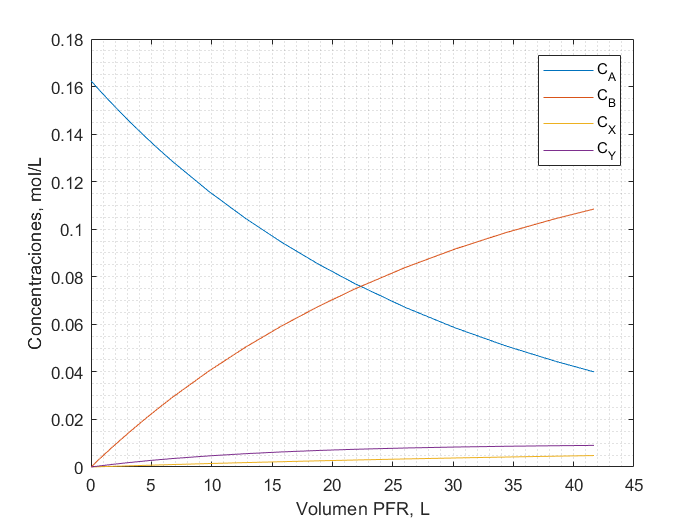

% Ci = [A,B,X,Y]

%Condiciones iniciales
Ci0 = [CA0,0,0,0] ;

%Sistema Ecuaciones
dCidV = @(Ci) [-(rX(T0,Ci(1))+rB(T0,Ci(1))+rY(T0,Ci(1)))/Q0;...
                rB(T0,Ci(1))/Q0 ;...
                rX(T0,Ci(1))/Q0 ;...
                rY(T0,Ci(1))/Q0 ] ;

%Intervalo de solución
vspan = [0,V1PFR] ;
[v,Ci] = ode15s(@(v,Ci) dCidV(Ci'),vspan,Ci0') ;
figure('color','white')
plot(v,Ci)
xlabel('Volumen PFR, L')
ylabel('Concentraciones, mol/L')
legend('C_A','C_B','C_X','C_Y','location','best')
grid minor

Y las concentraciones a la salida

CB1 = Ci(end,2) %mol/L

CB1 = 0.1085

CX1 = Ci(end,3) %mol/L

CX1 = 0.0048

CY1 = Ci(end,4) %mol/L

CY1 = 0.0091

Para el siguiente reactor, CSTR, el balance de materia para A es


$$F_{A,1} -  F_{A,2}  + R_A V_2= 0$$


Donde $R_A$ es la rapidez de reacción global, explicada anteriormente. Reescribirmos la expresión y encontramos el volumen


$$\rightarrow V_2= \frac{Q_0\left(C_{A,2}-C_{A,1}\right)}{R_{A,(C_{A,2})}}$$


Como también se tiene $x_{A2}=0.99$ entonces

CA2

CA2 = 0.0016

Encontrando

V2CSTR = Q0*(CA2-CA1)/(-rX(T0,CA2)-rB(T0,CA2)-rY(T0,CA2)) 

V2CSTR = 591.2378

De manera análoga al balance de materia elaborado para A, también se hace para las otras especies y se obtiene


$$C_{X,2}  = C_{X,1} + r_{X(C_{A,2})} \frac{V_1}{Q_0}$$



$$C_{B,2}  = C_{B,1}+r_{B(C_{A,2})} \frac{V_1}{Q_0}$$



$$C_{Y,2}  =C_{Y,1}+ r_{Y(C_{A,2})} \frac{V_1}{Q_0}$$


CX2 = CX1 + rX(T0,CA2)*V2CSTR/Q0

CX2 = 0.0143

CB2 = CB1 + rB(T0,CA2)*V2CSTR/Q0

CB2 = 0.1373

CY2 = CY1 + rY(T0,CA2)*V2CSTR/Q0

CY2 = 0.0091

Encontrando como selectividad global


$$\hat{S}_{B/XY} = \frac{F_{B2}}{F_{X2}+F_{Y2}} = \frac{C_{B2}}{C_{X2}+C_{Y2}}$$


SBXY = CB2/(CX2+CY2)

SBXY = 5.8489

y como rendimiento global de la reacción


$$\hat{Y}_{B} = \frac{F_{B2}}{F_{A0}-F_{A2}} = \frac{C_{B2}}{C_{A0}-C_{A2}}$$


YBXY = CB2/(CA0-CA2)

YBXY = 0.8539

Con el flujo de B a la salida del arreglo de

FBout = Q0*CB2 % molB/min

FBout = 1.3730

Resumiendo los resultados en las siguientes tablas

ResultadosPFR1 = [V1PFR;CA1;CB1;CX1;CY1] ;
ResultadosCSTR2 = [V2CSTR;CA2;CB2;CX2;CY2] ;
table(ResultadosPFR1,ResultadosCSTR2,'RowNames',{'V','CA','CB','CX','CY'})

ans = 5×2 table
          ResultadosPFR1    ResultadosCSTR2
          ______________    _______________

    V          41.689             591.24   
    CA           0.04          0.0016241   
    CB        0.10849             0.1373   
    CX      0.0048148           0.014345   
    CY      0.0090899          0.0091289   


P = FBout/(V1PFR+V2CSTR)

P = 0.0022

table(SBXY,YBXY,P)

ans = 1×3 table
     SBXY      YBXY          P    
    ______    _______    _________

    5.8489    0.85394    0.0021693


### C. Reactor CSTR

El balance de materia para el CSTR es


$$F_{A,0} -  F_{A,2}  + R_A V= 0$$


Y, por tanto el volumen se puede calcular como


$$\rightarrow V_{CSTR}= \frac{Q_0C_{A,2}-Q_0C_{A,0}}{R_{A,C_{A,2}}}$$


Con la concentración a la salida que cumple el 0.99 de conversión, se obtiene

VCSTR = Q0*(CA2-CA0)/(-rX(T0,CA2)-rB(T0,CA2)-rY(T0,CA2)) 

VCSTR = 2.4771e+03

Se hacen los balances para las otras especies


$$C_{X,2}  = r_{X(C_{A,2})} \frac{V_{CSTR}}{Q_0}$$



$$C_{B,2}  = r_{B(C_{A,2})} \frac{V_{CSTR}}{Q_0}$$



$$C_{Y,2}  = r_{Y(C_{A,2})} \frac{V_{CSTR}}{Q_0}$$


CX2 = rX(T0,CA2)*VCSTR/Q0

CX2 = 0.0399

CB2 = rB(T0,CA2)*VCSTR/Q0

CB2 = 0.1207

CY2 = rY(T0,CA2)*VCSTR/Q0

CY2 = 1.6334e-04

Y se calcula la selectividad global


$$\hat{S}_{B/XY} = \frac{F_{B2}}{F_{X2}+F_{Y2}} = \frac{C_{B2}}{C_{X2}+C_{Y2}}$$


SBXY = CB2/(CX2+CY2)

SBXY = 3.0102

y el rendimiento global de la reacción


$$\hat{Y}_{B} = \frac{F_{B2}}{F_{A0}-F_{A2}} = \frac{C_{B2}}{C_{A0}-C_{A2}}$$


YBXY = CB2/(CA0-CA2)

YBXY = 0.7506

Con el flujo de B a la salida del arreglo de

FBout = Q0*CB2 % molB/min

FBout = 1.2069

Se resumen los resultados en las siguientes tablas

Resultados = [VCSTR;CA2;CB2;CX2;CY2] ;
table(Resultados,'RowNames',{'V','CA','CB','CX','CY'})

ans = 5×1 table
          Resultados
          __________

    V         2477.1
    CA     0.0016241
    CB       0.12069
    CX       0.03993
    CY    0.00016334


P = FBout/(VCSTR)

P = 4.8722e-04

table(SBXY,YBXY,P)

ans = 1×3 table
     SBXY      YBXY          P     
    ______    _______    __________

    3.0102    0.75063    0.00048722


### D. Reactor PFR

Realizamos el balance de materia de A para el reactor PFR


$$\frac{dF_A}{dV} = R_A$$



$$\rightarrow V_{PFR} =Q_0 \int_{C_{A0}}^{C_{A2}} \frac{dC_A}{R_{A,(C_A)}$$


Donde

CA0

CA0 = 0.1624

CA2

CA2 = 0.0016

Luego,

VPFR = Q0*integral(@(CA) -1./(rX(T0,CA)+rB(T0,CA)+rY(T0,CA)),CA0,CA2)

VPFR = 132.8805

Nuevamente se realiza el balance para todas las especies


$$\frac{dC_A}{dV} =  R_A = \frac{-r_{X,(C_A)}-r_{Y,(C_A)}-r_{B,(C_A)}}{Q_0}$$



$$\frac{dC_B}{dV} = \frac{r_{,(C_A)}}{Q_0}$$



$$\frac{dC_X}{dV} = \frac{r_{B,(C_A)}}{Q_0}$$



$$\frac{dC_Y}{dV} = \frac{r_{Y,(C_A)}}{Q_0}$$


Y se resuelve el sistema de ecuaciones hasta $V_{1,PFR}$ teniendo en cuenta que en $V=0$ se tendrán las concentraciones de entrada $C_{i,0}$. Encontrando los siguientes perfiles de concentraciones

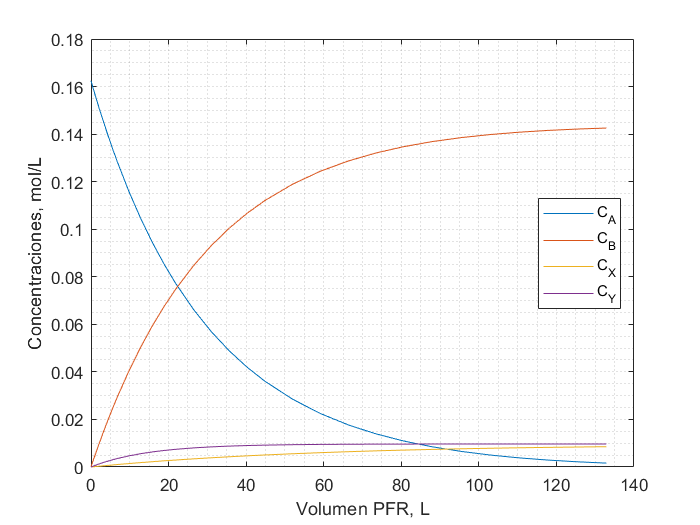

% Ci = [A,B,X,Y]

%Condiciones iniciales
Ci0 = [CA0,0,0,0] ;

%Sistema Ecuaciones
dCidV = @(Ci) [-(rX(T0,Ci(1))+rB(T0,Ci(1))+rY(T0,Ci(1)))/Q0;...
                rB(T0,Ci(1))/Q0 ;...
                rX(T0,Ci(1))/Q0 ;...
                rY(T0,Ci(1))/Q0 ] ;

%Intervalo de solución
vspan = [0,VPFR] ;
[v,Ci] = ode15s(@(v,Ci) dCidV(Ci'),vspan,Ci0') ;
figure('color','white')
plot(v,Ci)
xlabel('Volumen PFR, L')
ylabel('Concentraciones, mol/L')
legend('C_A','C_B','C_X','C_Y','location','best')
grid minor

Y las concentraciones a la salida

CB2 = Ci(end,2) %mol/L

CB2 = 0.1426

CX2 = Ci(end,3) %mol/L

CX2 = 0.0085

CY2 = Ci(end,4) %mol/L

CY2 = 0.0097

Encontrando como selectividad global


$$\hat{S}_{B/XY} = \frac{F_{B2}}{F_{X2}+F_{Y2}} = \frac{C_{B2}}{C_{X2}+C_{Y2}}$$


SBXY = CB2/(CX2+CY2)

SBXY = 7.8243

y como rendimiento global de la reacción


$$\hat{Y}_{B} = \frac{F_{B2}}{F_{A0}-F_{A2}} = \frac{C_{B2}}{C_{A0}-C_{A2}}$$


YBXY = CB2/(CA0-CA2)

YBXY = 0.8866

Con el flujo de B a la salida del arreglo de

FBout = Q0*CB2 % molB/min

FBout = 1.4256

Y se resumen los resultados a continuación

Resultados = [VPFR;CA2;CB2;CX2;CY2] ;
table(Resultados,'RowNames',{'V','CA','CB','CX','CY'})

ans = 5×1 table
          Resultados
          __________

    V        132.88 
    CA    0.0016241 
    CB      0.14256 
    CX    0.0085377 
    CY     0.009682 


P = FBout/(VPFR)

P = 0.0107

table(SBXY,YBXY,P)

ans = 1×3 table
     SBXY      YBXY         P    
    ______    _______    ________

    7.8243    0.88664    0.010728
